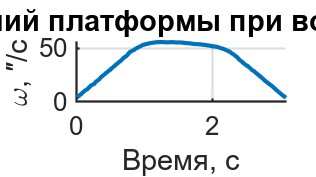


load("first_OMC_measure.mat")

% --- настройки внешности -----------------------------------------------
figure('Units','pixels', ...
       'Position',[100 100 960 540], ...   % 16:9 — удобно для слайда
       'Color','w');                       % белый фон

plot(flyweelvelocity.t, flyweelvelocity.v, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\omega, ″/с', 'FontSize',18);

title('Скорость колебаний платформы при воздействии маховика', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 

% --- экспорт ------------------------------------------------------------
exportgraphics(gcf, 'flywheel_velocity.png', 'Resolution',300);

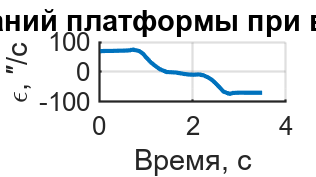

%----------------------------------------------------------------------
plot(flyweelacceleration.t,flyweelacceleration.a, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\epsilon, ″/с', 'FontSize',18);

title('Ускорение колебаний платформы при воздействии маховика', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'flywheel_acc.png', 'Resolution',300);

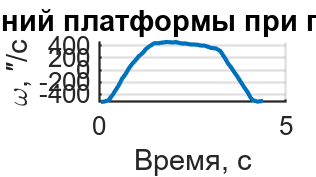

%------------------------------------------------------------------
plot(OMCvelocity.t,OMCvelocity.v*6, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\omega, ″/с', 'FontSize',18);

title('Скорость колебаний платформы при повороте ОМС (Ось Z)', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'Z_veloctirt.png', 'Resolution',300);

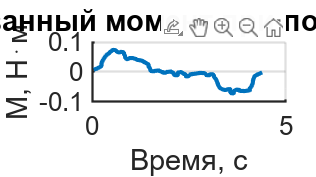


%---------------------------------------
Zmom = acc/max(flyweelacceleration.a)*0.005;
plot(OMCacceleration.t,Zmom, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('М, Н⋅м', 'FontSize',18);

title('Некомпенсированный момент при повороте ОМС (Ось Z)', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 

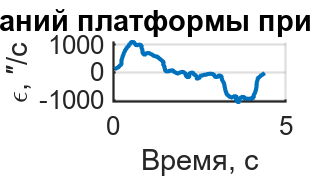

exportgraphics(gcf, 'Z_acc.png', 'Resolution',300);


plot(OMCacceleration.t,acc, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\epsilon, ″/с', 'FontSize',18);

title('Ускорение колебаний платформы при повороте ОМС (Ось Z)', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'Z_mom.png', 'Resolution',300);

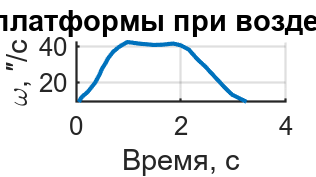



load("first_OMC_measure.mat")

% --- настройки внешности -----------------------------------------------
figure('Units','pixels', ...
       'Position',[100 100 960 540], ...   % 16:9 — удобно для слайда
       'Color','w');                       % белый фон

plot(fwvy.x, fwvy.y, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\omega, ″/с', 'FontSize',18);

title('Скорость колебаний платформы при воздействии маховика (Ось Y)', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 

% --- экспорт ------------------------------------------------------------
exportgraphics(gcf, 'flywheel_velocityY.png', 'Resolution',300);

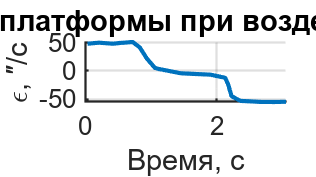

%----------------------------------------------------------------------
fway(end,:)=[];
plot(fway.x,fway.y, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\epsilon, ″/с', 'FontSize',18);

title('Ускорение колебаний платформы при воздействии маховика, (Ось Y)', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'flywheel_accY.png', 'Resolution',300);

%------------------------------------------------------------------
plot(OMCvelocity.t,OMCvelocity.v*6, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\omega, ″/с', 'FontSize',18);

title('Скорость колебаний платформы при повороте ОМС (Ось Z)', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'Y_veloctirt.png', 'Resolution',300);


%---------------------------------------
acc = movmean(OMCacceleration.a, 6);
acc = acc*6;
plot(OMCacceleration.t,acc, ...
     'LineWidth',2.5, ...
     'Color',[0 0.447 0.741]);             % «MATLAB-blue»

xlabel('Время, с',        'FontSize',18);
ylabel('\epsilon, ″/с', 'FontSize',18);

title('Ускорение колебаний платформы при повороте ОМС (Ось Z)', ...
      'FontSize',20, 'FontWeight','bold');

% --- оформление осей ----------------------------------------------------
ax            = gca;
ax.FontSize   = 16;
ax.FontName   = 'Helvetica';
ax.LineWidth  = 1.4;
ax.Box        = 'off';        % без рамки
% ax.GridAlpha  = 0.15;         % прозрачность основной сетки
% ax.MinorGridAlpha = 0.30;     % и мелкой
grid on; 
exportgraphics(gcf, 'Y_acc.png', 'Resolution',300);